%% load data
cd('~/Develop/Phix_mutagenesis/Data/')
load Stat
% O2N = load('DS_Info_o2n')
% DS = join(O2N.D,D,'Key',{'Position' 'Nt' 'NtSubstitute' 'PreNt' 'PostNt' },'type','inner');
% clear 'O2N' 'D';
D = sortrows(D , {'Position'  'NtSubstitute' });
D.Nt = categorical(D.Nt);
D.NtSubstitute = categorical(D.NtSubstitute);
D.medianFreq_o2n( D.Nt == D.NtSubstitute)  = NaN ; 

%% correlation between O2N & zscore

Y = D.medianFreq_o2n ; 
Y(Y>prctile(Y,99.5))=prctile(Y,99.5); 
D.grp = round(5*log2(Y)); 
D.Z = nanmean([D.z1_0402 D.z1_0316],2) ; 
G = grpstats(D,'grp',{'median' 'std'},'DataVars',{'Z'}) ; 
figure ; 
boxplot( D.Z ,D.grp,'symbol','','PlotStyle','compact'); 
hold on; 
plot( G.median_Z ,'-k','LineWidth',3);
ylim([-1 4])
grid on ; 
ylabel('mean Z_{score}')
xlabel('O2N median freq')
line(xlim,[0 0])
title( sprintf('Spearman corr = %0.03f' ,...
    corr(D.medianFreq_o2n ,D.Z,'rows','complete','Type','Spearman')))


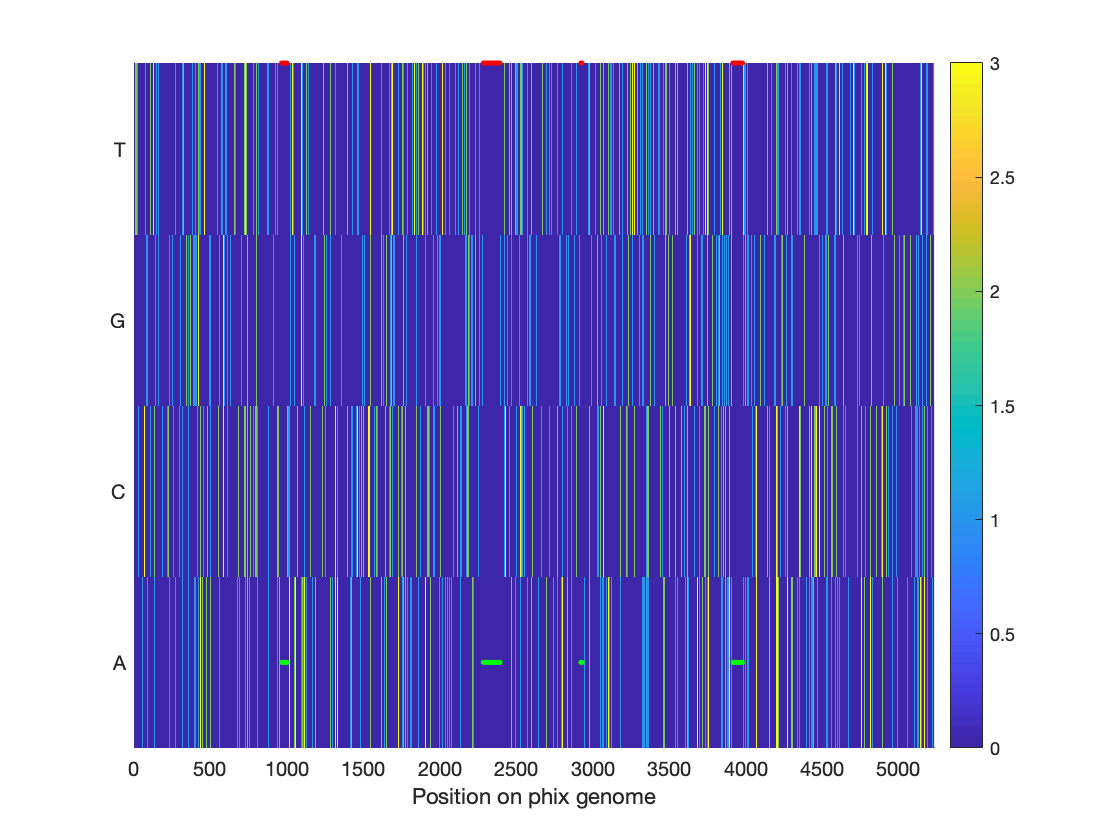

%% Identify regions depleted for standing variation
THRESH = 90 ; 
X = [D.z1_0316  D.z1_0402 D.medianFreq_o2n];
%X( strcmp(D.ConservationScore , 'Synonymous') , :) = 0 ;% FUCK. thinking bug!
X1 = reshape(X(:,1),4,[]); X1(X1<prctile(X1(:),THRESH)) = 0 ; X1(X1>=prctile(X1(:),THRESH)) = 1 ; 
X2 = reshape(X(:,2),4,[]); X2(X2<prctile(X2(:),THRESH)) = 0 ; X2(X2>=prctile(X2(:),THRESH)) = 1 ;
X3 = reshape(X(:,3),4,[]); X3(X3<prctile(X3(:),THRESH)) = 0 ; X3(X3>=prctile(X3(:),THRESH)) = 1 ;
figure;  hold on ;
imagesc((X1+X2+X3) , [0 3] )
set(gca,'ytick',1:4);set(gca,'yticklabel',{'A' 'C' 'G' 'T'})
xlabel('Position on phix genome')
colorbar

noncoding = D.Position(cellfun(@isempty,D.Genes) & D.NtSubstitute=='A' ) ; 
plot( D.Position(~D.IN_ORF) , 1 ,'.g')
plot( noncoding , repmat(4.5 , 1 , numel(noncoding)) ,'.r' )
xlim([0 5233])

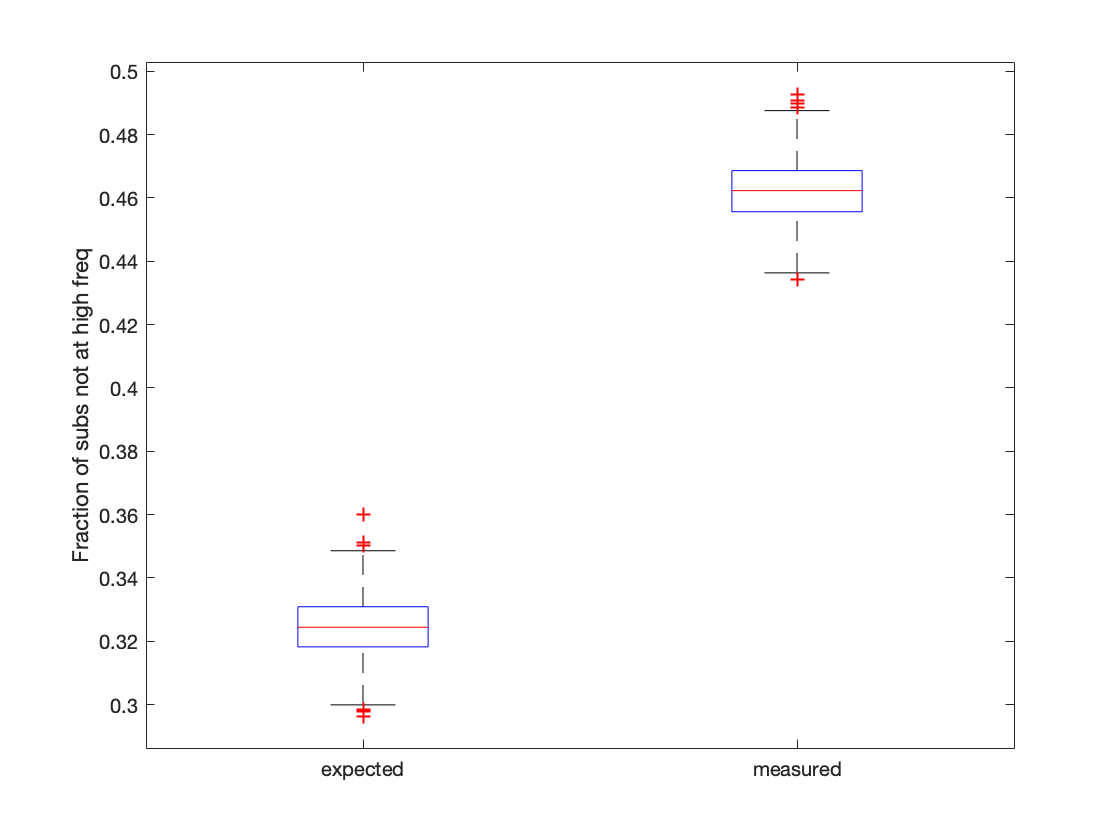

%% statistical test for agreement of depletion of standing variation across experiments
m = NaN(1e3,2);
for I = 1:1000
    idx = randsample( size(X1,2) , round(size(X1,2)/2) , true);
    m1 = mean(sum(X1(:,idx))==0);
    m2 = mean(sum(X2(:,idx))==0);
    m3 = mean(sum(X3(:,idx))==0);
    m(I,1) = m1*m2*m3;
    m(I,2) = mean( sum(X1(:,idx)+X2(:,idx)+X3(:,idx)) == 0);
end
figure; 
boxplot(m)
set(gca,'xticklabel',{'expected' 'measured'})
ylabel('Fraction of subs not at high freq')